corners(1, :)

ans =     80   543


test = find_neighbors(corners, 1, x_diff_range, y_diff_range)

diff_x = 67

diff_y = 138

diff_x = 67

diff_y = 180

test =    218   476
   260   610



imshow(img_grey);

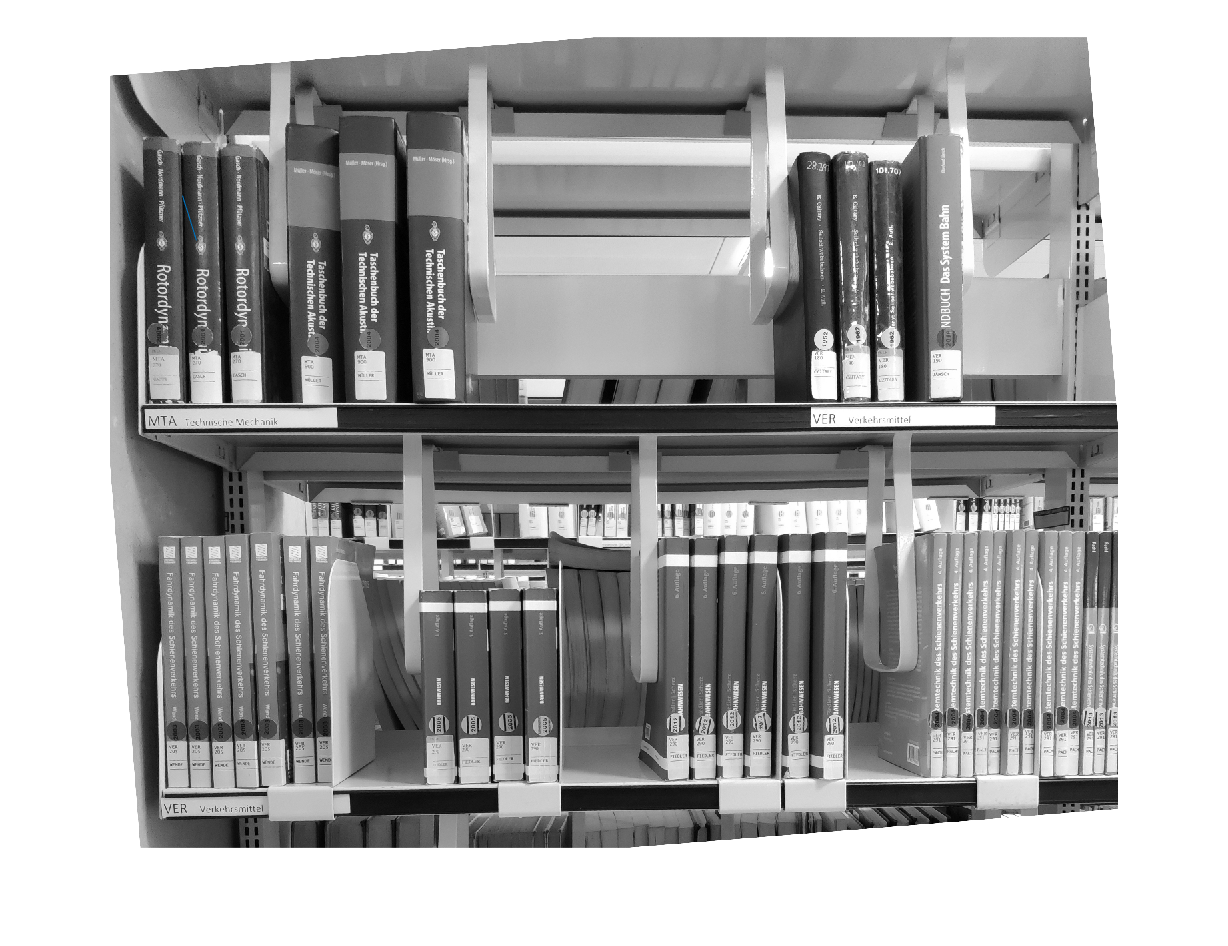

hold on;
plot([test(:, 1)], [test(:, 2)]);
hold off;


function result = find_neighbors(coords, coords_target_index, x_diff_range, y_diff_range)
    % find nearest neighbors in range
    
    result = [];
    for j = coords_target_index + 1:size(coords, 1)
        neighbor = coords(j, :);
        if check_for_range(coords(coords_target_index, :), neighbor, x_diff_range, y_diff_range)
            %disp(corners_x(i,:));
            %disp(next);
            %plot([corners_x(i,1), next(1,1)], [corners_x(i,2), next(1,2)]); 
            result = [result; neighbor];
        end
    end
    
end

%check if the two points are not too far from each other
function result = check_for_range(coordA, coordB, x_diff_range, y_diff_range)

    diff_x = abs(coordA(2) - coordB(2));
    diff_y = abs(coordA(1) - coordB(1));
    
    result = diff_x >= x_diff_range(1) && ...
             diff_x <= x_diff_range(2) && ...
             diff_y >= y_diff_range(1) && ...
             diff_y <= y_diff_range(2);
         
     if result
         diff_x
         diff_y
     end
   
end